filename = 'NonInstrumental-SPE-03-30-2020(01)';
load([filename,'_D.mat']);

Calculate average total cue visible time by condition(i.e. reward size) over session

let's do this block by block

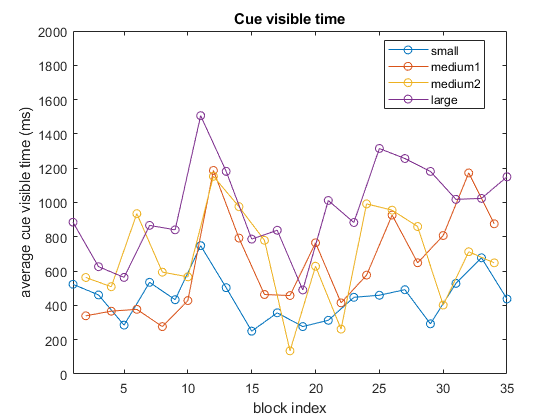

visibletimeByTrial = NaN(D.TrialNumber(end),1);
conds = NaN(size(visibletimeByTrial));
visibletimeByBlock = NaN(D.BlockIndex(end),4); 
blocks = 1:D.BlockIndex(end);

visibletimeThisBlock = zeros(4,1);
trialCount = zeros(4,1);
for trind =  1:length(D.TrialNumber)
    if D.Rewarded(trind)
        if strcmp(D.CueName{trind},'stimA') 
            cond = 1;
        elseif strcmp(D.CueName{trind},'stimB1') 
            cond = 2;
        elseif strcmp(D.CueName{trind},'stimB2') 
            cond = 3;
        else
            cond = 4;
        end
        trialCount(cond) = trialCount(cond) + 1;
        visibletimeThisBlock(cond) = ...
            visibletimeThisBlock(cond) + sum(D.CueIsOn{trind});
        visibletimeByTrial(trind) = sum(D.CueIsOn{trind});
        conds(trind) = cond;
    end
    if trind==length(D.TrialNumber) || D.BlockIndex(trind)~=D.BlockIndex(trind+1)
        for cond = 1:4
            if trialCount(cond)==0
                continue;
            end
            visibletimeByBlock(D.BlockIndex(trind-1),cond) = ...
                visibletimeThisBlock(cond)/trialCount(cond);
        end
        visibletimeThisBlock = zeros(4,1);
        trialCount = zeros(4,1);
    end
end


figure;
for cond = 1:4
    plot(blocks(~isnan(visibletimeByBlock(:,cond))),...
        visibletimeByBlock(~isnan(visibletimeByBlock(:,cond)),cond),'-o','MarkerSize',6);
    hold on;
end

ylim([0,2000]);xlim([1,blocks(end)]);
xlabel('block index');
ylabel('average cue visible time (ms)')
legend({'small','medium1','medium2','large'},'location','best');
title('Cue visible time')
saveas(gcf,['visible_time',filename(find(filename=='-',1):end),'.png']);

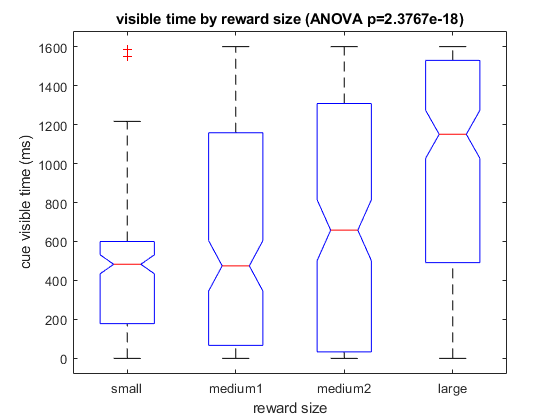


visibletimeByTrial = visibletimeByTrial(~isnan(visibletimeByTrial));
conds = conds(~isnan(conds));
p = anova1(visibletimeByTrial,conds,'off');
figure;
boxplot(visibletimeByTrial,conds,'notch','on');
xticklabels({'small','medium1','medium2','large'});
xlabel('reward size');ylabel('cue visible time (ms)');
title(['visible time by reward size (ANOVA p=',num2str(p),')'])
saveas(gcf,['visible_time_ANOVA',filename(find(filename=='-',1):end),'.png']);